# **General Guide**

### **Fitting the MATLAB Logo Using Neural Networks**

This live script demonstrates the workflow of using a neural network for regression. The first five sections provide 

detailed usage instructions, while **the sixth section offers quick commands that allow users to solve fitting **

**problems with just a few lines of code. (read the first section to make sure the format of the data are **

**correct)**

### 1. **Format Requirement**

To represent neural network computations using linear algebra notation, 

both the input data and corresponding labels should be column vectors.

For example: $f\left(x_1 ,x_2 \right):R^2 \to R^2 =\left(x_1^2 +x_2^2 ,{2x}_1^2 +x_2^2 \right)$

                                                                 
$$\begin{array}{l}
{\mathit{\mathbf{d}}}_1 =\left\lbrack \begin{array}{c}
1\\
1
\end{array}\right\rbrack \;,{\mathit{\mathbf{d}}}_2 \;=\left\lbrack \begin{array}{c}
1\\
2
\end{array}\right\rbrack ,\;\cdots \;,{\mathit{\mathbf{d}}}_N =\left\lbrack \begin{array}{c}
x_{1N} \\
x_{2N} 
\end{array}\right\rbrack \\
{\mathit{\mathbf{y}}}_1 =\left\lbrack \begin{array}{c}
1\\
3
\end{array}\right\rbrack \;,{\;\mathit{\mathbf{y}}}_2 \;=\;\left\lbrack \begin{array}{c}
5\\
9
\end{array}\right\rbrack ,\;\cdots \;,{\mathit{\mathbf{y}}}_N \;=\left\lbrack \begin{array}{c}
x_{1N}^2 +x_{2N}^2 \\
{2x}_{1N}^2 +x_{2N}^2 
\end{array}\right\rbrack 
\end{array}$$


    data : $\mathit{\mathbf{D}}\in R^{n_D \times N}$ ($n_D \times N$ Matrix), where $n_D$ is the dimension of data and $N$ is the number of data points. 

    label : $\mathit{\mathbf{Y}}\in R^{n_L \times N}$($n_L \times N$ Matrix), where $n_L$ is the dimension of label.

                                                                
$$\mathit{\mathbf{D}}=\left\lbrack \begin{array}{cccc}
1 & 1 & \cdots  & x_{1N} \\
1 & 2 & \cdots  & x_{2N} 
\end{array}\right\rbrack ,\;\;\mathit{\mathbf{Y}}=\left\lbrack \begin{array}{cccc}
1 & 5 & \cdots  & x_{1N}^2 +x_{2N}^2 \\
3 & 9 & \cdots  & {2x}_{1N}^2 +x_{2N}^2 
\end{array}\right\rbrack$$


% Generate Data
clear; clc; close all;
n=15;
x=1:2*n+1; y=1:2*n+1;
[X,Y]=meshgrid(x,y);
V=membrane(1,n);
Predictor=[X(:),Y(:)]';
Response=V(:)';

data=Predictor;
label=Response;

### 2. Data Visualization

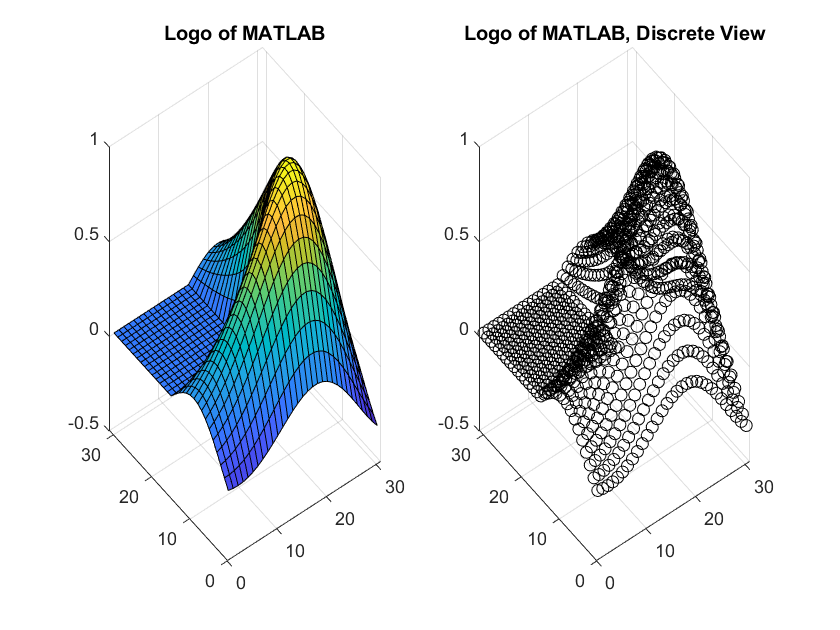

GridNumber=numel(x);
figure
subplot(1,2,1)
surf(X,Y,reshape(label,GridNumber,GridNumber))
title('Logo of MATLAB')
subplot(1,2,2)
scatter3(data(1,:),data(2,:),label,'black')
title('Logo of MATLAB, Discrete View')

Our goal is to find a surface that represents the input-output relation between the data and label.

### 3. Specify The Structure & Type of Neural Networks

The package support two types of Neural Nets for function approximation & data fitting,

the first is Multilayer Perceptron (MLP) , the second is Residual Neural Networks (ResNet).

**ResNet can make training neural networks easier, the effectiveness is particularly **

**evident when the network is very deep.**

To specify the type of network, use the command: `NN.NetworkType='ANN'` or `'ResNet'`, 

close all
NN.NetworkType='ANN'; % MLP

The logo of MATLAB is a function with 2 input 1 output, i.e.$\;f\left(\mathit{\mathbf{x}}\right):R^2 \to R$ 

Define the network structure using following command:

InputDimension=2; OutputDimension=1;
LayerStruct=[InputDimension,8,8,8,OutputDimension];

**The number between Input & OutputDimension are the size of hidden layers,**

**larger hidden layer sizes and deeper networks lead to better approximation of complex functions**.

To specify the cost function to minimize using `NN.Cost`, you can choose between 

two options provided by the package : the Sum of Square Error (SSE) and the Mean Square Error (MSE).


$$J_{\mathrm{SSE}} \left(\mathit{\mathbf{W}},\mathit{\mathbf{b}}\right)\equiv \|\mathit{\mathbf{Y}}-\mathbf{NN}\left(\mathit{\mathbf{W}},\mathit{\mathbf{b}},\mathit{\mathbf{D}}\right){\left\|\right.}^2 ,\;\;J_{\mathrm{MSE}} \left(\mathit{\mathbf{W}},\mathit{\mathbf{b}}\right)\equiv \frac{\left\|\mathit{\mathbf{Y}}-\mathbf{NN}\left(\mathit{\mathbf{W}},\mathit{\mathbf{b}},\mathit{\mathbf{D}}\right){\left\|\right.}^2 \right.}{n_D }$$


NN.Cost='SSE'; 

You can specify the nonlinear activation function for your neural network using `NN.ActivationFunction`.

Currently, there are four built-in activation functions available, which are:

1. Gaussian 

2. Sigmoid

3. tanh

4. ReLU

The recommended activation function for function approximation is `'Gaussian'`.

NN.ActivationFunction='Gaussian';

You can also use a function handle to define custom activation function.

When using function handles to define custom activation, remember to provide the derivatives as well.

% NN.ActivationFunction=@(x) exp(-x.^2);
% NN.activeDerivate=@(x) -2*x.*exp(-x.^2); % derivate of gaussian

The activation should be smooth for function approximation problems, so those commonly used activation for 

classification problems like 'ReLU' are not recommand.

Finally, use the command 'Initialization' to Initialize the weights & biases of NN.

NN=Initialization(LayerStruct,NN);

### 4. Solve Least Square Problem By Numerical Optimization

Our goal is to find optimal parameters ${\mathit{\mathbf{W}}}^* ,{\mathit{\mathbf{b}}}^*$ such that minimize the cost function $J\left(\mathit{\mathbf{W}},\mathit{\mathbf{b}}\right)$ , i.e.


$${\mathit{\mathbf{W}}}^* ,{\mathit{\mathbf{b}}}^* \;=\;\textrm{argmin}\;\;\left\|\mathit{\mathbf{Y}}-\textrm{NN}\left(\mathit{\mathbf{W}},\mathit{\mathbf{b}},\mathit{\mathbf{D}}\right){\left\|\right.}^2 \right.$$


The standard workflow can be separated into two stages. First use stochastic gradient descent-based methods (SGD)

 to avoid getting stuck in local minima. For SGD-based algorithms, the following information is required:

#### 4.1 Stochastic Gradient Descent Based Method

option.Solver='ADAM';
option.BatchSize=100;
option.MaxIteration=20;
option.s0=2e-3; % Step Size

Start optimizing using Adaptive Momentum Estimation. (ADAM)

NN=OptimizationSolver(data,label,NN,option);

Iteration : 1 , Cost :      87.40805614 
Iteration : 2 , Cost :      84.50008922 
Iteration : 3 , Cost :      82.17817358 
Iteration : 4 , Cost :      78.75882006 
Iteration : 5 , Cost :      74.65420815 
Iteration : 6 , Cost :      69.68327716 
Iteration : 7 , Cost :      63.72717552 
Iteration : 8 , Cost :      57.21862755 
Iteration : 9 , Cost :      51.32185497 
Iteration : 10 , Cost :      45.40799044 
Iteration : 11 , Cost :      40.79798658 
Iteration : 12 , Cost :      37.04029401 
Iteration : 13 , Cost :      34.53779423 
Iteration : 14 , Cost :      32.19926879 
Iteration : 15 , Cost :      30.81699083 
Iteration : 16 , Cost :      29.29917356 
Iteration : 17 , Cost :      28.43830068 
Iteration : 18 , Cost :      27.16526463 
Iteration : 19 , Cost :      26.89070376 
Iteration : 20 , Cost :      25.74577724 
------------------------------------------------------
Max Iteration : 20 , Cost :      25.74577724 
Optimization Time :   0.4
Mean Absolute Error :   0.1191
-----------

#### 4.2 Quasi-Newton Method

Quasi-Newton methods are much superior to SGD-Based methods (superlinear v.s. linear convergence rate) 

in small-to-medium-size least-square problems, using Quasi-Newton methods can significantly accelerate the 

optimization.

The following information are required when using Quasi-Newton's methods.

If the infinity norm of the gradient is less than terminate condition, the optimization process will be stop.

option.Solver='BFGS';
option.MaxIteration=550;
option.TerminateCondition=1e-6; % optional

Start optimizing using Broyden-Fletcher-Goldfarb-Shanno method (BFGS).

NN=OptimizationSolver(data,label,NN,option);

Iteration : 27 , Cost :      18.83059677 
Iteration : 54 , Cost :       2.06492154 
Iteration : 81 , Cost :       1.37540596 
Iteration : 108 , Cost :       0.55065572 
Iteration : 135 , Cost :       0.20217241 
Iteration : 162 , Cost :       0.13828054 
Iteration : 189 , Cost :       0.10295504 
Iteration : 216 , Cost :       0.07890743 
Iteration : 243 , Cost :       0.06447174 
Iteration : 270 , Cost :       0.05247506 
Iteration : 297 , Cost :       0.04520467 
Iteration : 324 , Cost :       0.03454883 
Iteration : 351 , Cost :       0.02714906 
Iteration : 378 , Cost :       0.02393285 
Iteration : 405 , Cost :       0.02120411 
Iteration : 432 , Cost :       0.01882122 
Iteration : 459 , Cost :       0.01638477 
Iteration : 486 , Cost :       0.01430803 
Iteration : 513 , Cost :       0.01264098 
Iteration : 540 , Cost :       0.01170897 
------------------------------------------------------
Max Iteration : 550 , Cost :       0.01129742 
Optimization Time :   4.6
Mean Absolute E

### 5. Quatify & Visualize Fitting Performance

Use NN.Evaluate to predict & analyzing fitting results. 

you can quatify the fitting performance  by the error vector : $\mathit{\mathbf{E}}=\mathit{\mathbf{Y}}-\textrm{NN}\left(\mathit{\mathbf{D}}\right),\;\;\;\mathit{\mathbf{E}}\in \;R^{1\times N}$

or use the function `"FittingReport"` to quantify and visualize the performance rapidly.

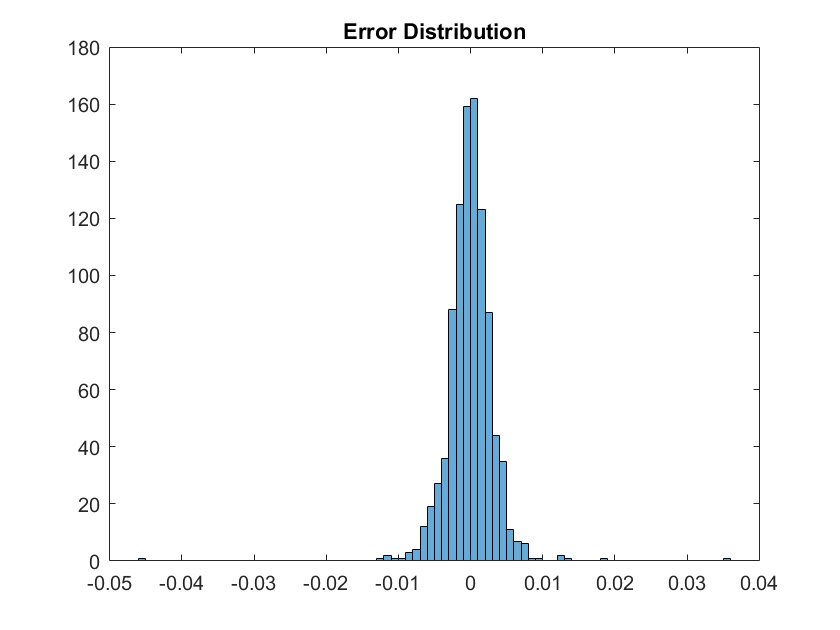

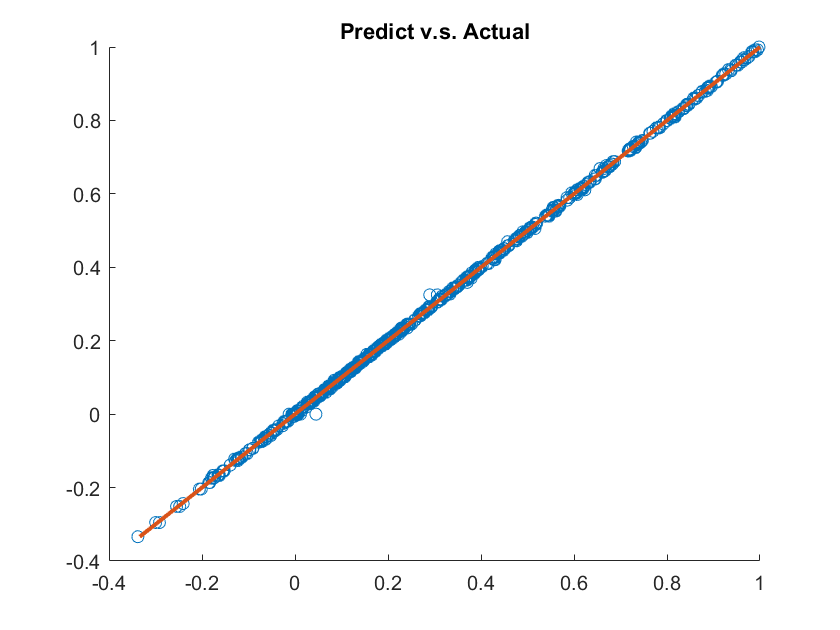

Prediction=NN.Evaluate(data);
Report=FittingReport(data,label,NN);

Visualize the optimized neural network

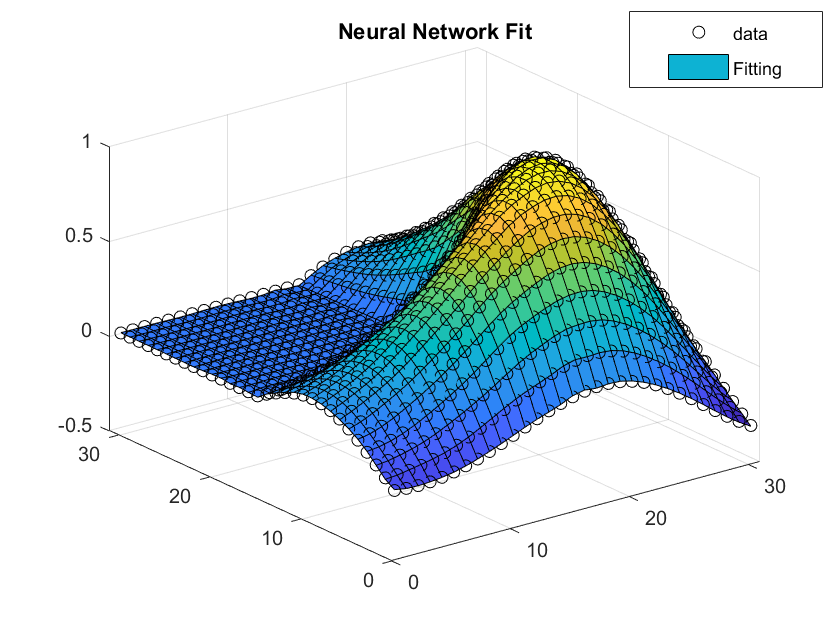

figure
scatter3(data(1,:),data(2,:),label(1,:),'black') 
hold on
[X,Y]=meshgrid(x,y);
n1=numel(x); n2=numel(y);
surf(X,Y,reshape(Prediction(1,:),n1,n2))
title('Neural Network Fit')
legend('data','Fitting')
legend("Position", [0.74834,0.86095,0.23184,0.12127])

FirstOrderOptimality=NN.FirstOrderOptimality

FirstOrderOptimality = 0.2310

The first order optimality may indicate the fitting potential of neural net, if the first order optimality is still large after optimization, you may consider using the BFGS method for further optimization of the neural network.

option.Solver='BFGS';
option.MaxIteration=100;
NN=OptimizationSolver(data,label,NN,option);

Iteration : 5 , Cost :       0.01129557 
Iteration : 10 , Cost :       0.01129185 
Iteration : 15 , Cost :       0.01128888 
Iteration : 20 , Cost :       0.01128624 
Iteration : 25 , Cost :       0.01128433 
Iteration : 30 , Cost :       0.01128140 
Iteration : 35 , Cost :       0.01127808 
Iteration : 40 , Cost :       0.01127449 
Iteration : 45 , Cost :       0.01126981 
Iteration : 50 , Cost :       0.01126210 
Iteration : 55 , Cost :       0.01125502 
Iteration : 60 , Cost :       0.01124501 
Iteration : 65 , Cost :       0.01122934 
Iteration : 70 , Cost :       0.01121344 
Iteration : 75 , Cost :       0.01119411 
Iteration : 80 , Cost :       0.01116980 
Iteration : 85 , Cost :       0.01111361 
Iteration : 90 , Cost :       0.01101895 
Iteration : 95 , Cost :       0.01092824 
Iteration : 100 , Cost :       0.01080288 
------------------------------------------------------
Max Iteration : 100 , Cost :       0.01080288 
Optimization Time :   0.9
Mean Absolute Error :   0.0021
-

clear option; % clear solver setting for next section.

### 6. Train Neural Network Quickly with a Few Lines of Code

If the user did not provide solver options, the pack will perform the two-stage optimization automatically, 

that is, using 'ADAM' to find better initial parameters for the Quasi-Newton method, than applying 'BFGS'

solver to accelerate convergence.

% Structure Set Up
InputDimension=2; OutputDimension=1;
LayerStruct=[InputDimension,7,7,8,7,7,OutputDimension];
NN=Initialization(LayerStruct);
% Solver Set Up
option.MaxIteration=600;
NN=OptimizationSolver(data,label,NN,option);

Iteration : 7 , Cost :       0.17647171 
Iteration : 14 , Cost :       0.10864026 
Iteration : 21 , Cost :       0.09271308 
Iteration : 28 , Cost :       0.08575096 
Iteration : 35 , Cost :       0.08049857 
Iteration : 42 , Cost :       0.07396149 
Iteration : 49 , Cost :       0.07216257 
Iteration : 56 , Cost :       0.06921750 
Iteration : 63 , Cost :       0.06710528 
Iteration : 70 , Cost :       0.06762928 
Iteration : 77 , Cost :       0.06524048 
Iteration : 84 , Cost :       0.06222377 
Iteration : 91 , Cost :       0.06393177 
Iteration : 98 , Cost :       0.06045880 
Iteration : 105 , Cost :       0.05409182 
Iteration : 112 , Cost :       0.05603869 
Iteration : 119 , Cost :       0.03094352 
Iteration : 126 , Cost :       0.02638018 
Iteration : 133 , Cost :       0.02015182 
Iteration : 140 , Cost :       0.01562922 
Iteration : 147 , Cost :       0.01431934 
------------------------------------------------------
First Stage Optimization Finished in  150  Iteration.
---

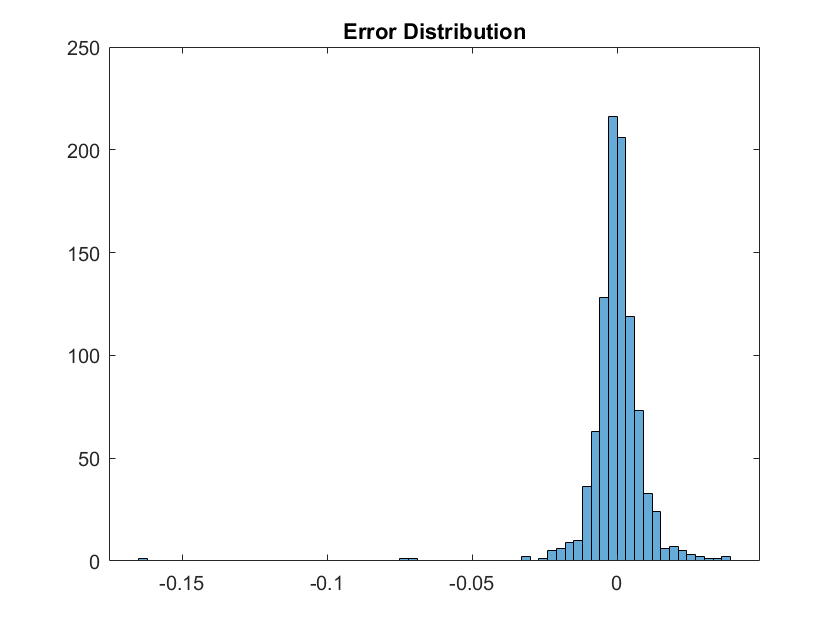

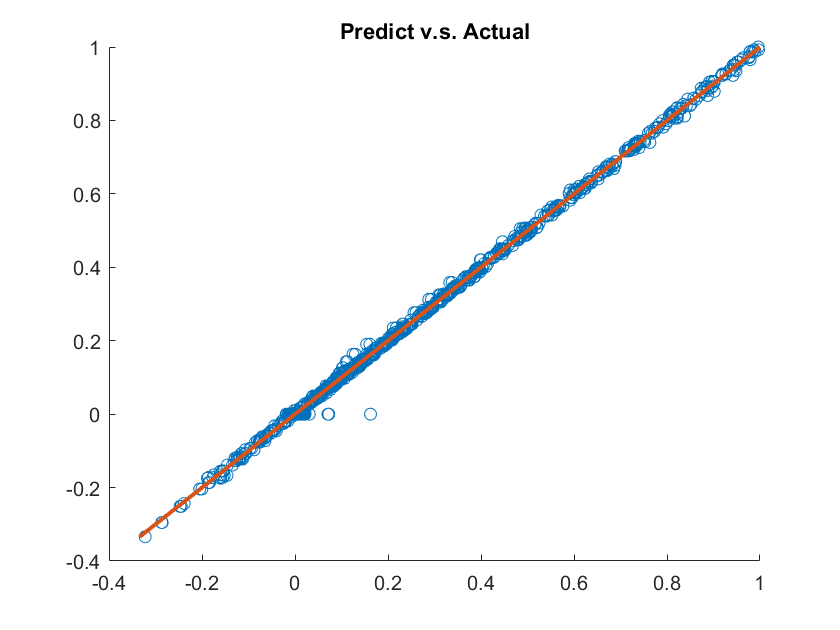

% Validate Results
Report=FittingReport(data,label,NN);